EX4 p.56

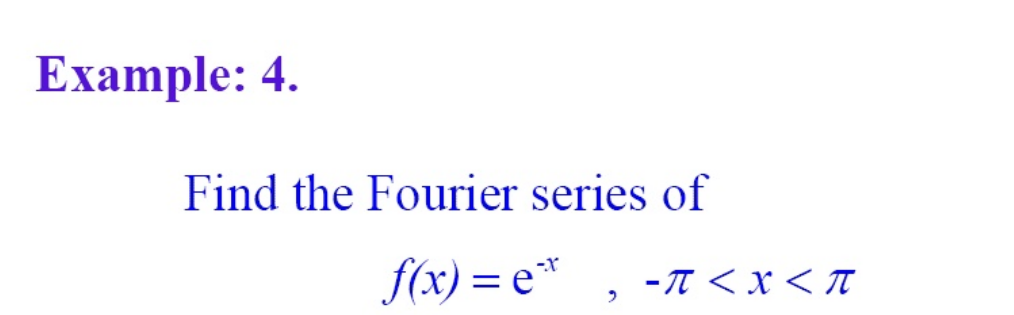

clear 
clf
syms x n sigma;
f=exp(-x);
a0=eval((1/pi)*int(f,x,[-pi pi]))

a0 = 7.3522

assume(n,"integer")
an =simplify((1/pi)*int(f*cos(n*x),x,[-pi pi]))

$$an = \frac{5734161139222659\,{\left(-1\right)}^{n}\,\sinh\left(\pi \right)}{9007199254740992\,\left(n^{2}+1\right)}$$

bn=simplify((1/pi)*int(f*sin(n*x),x,[-pi pi]))

$$bn = -\frac{5734161139222659\,{\left(-1\right)}^{n+1}\,n\,\sinh\left(\pi \right)}{9007199254740992\,\left(n^{2}+1\right)}$$

f0=simplify(an*cos(n*x)+bn*sin(n*x));
fn=[sigma simplify(an*cos(n*x)+bn*sin(n*x))]

$$fn = \left(\begin{array}{cc} \sigma & \frac{5734161139222659\,{\left(-1\right)}^{n}\,\sinh\left(\pi \right)\,\left(\cos\left(n\,x\right)+n\,\sin\left(n\,x\right)\right)}{9007199254740992\,\left(n^{2}+1\right)} \end{array}\right)$$

fprintf('%s+%s',a0/2,fn)

3.676078e+00+sigma(5734161139222659*(-1)^n*sinh(pi)*(cos(n*x) + n*sin(n*x)))/(9007199254740992*(n^2 + 1))+

harm = 7;%number of harmonics

Plot graphs

for i =1:harm
    fx =a0/2+symsum(f0,n,[1 i]);
    subplot(harm+1,1,i)
    fplot(fx,[-pi pi])
    title("Harmonic")
    xlabel('time')
end
hold on

plot input 

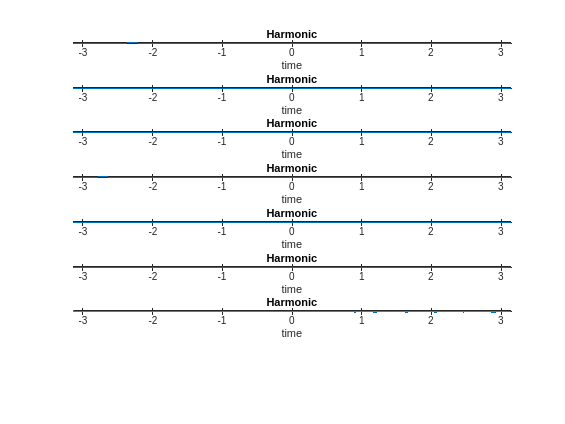

t=-pi:1/1000:pi;
y=exp(-t);
plot(t,y)
ylim([exp(-pi) exp(pi)])
grid on

Spectrum plot 

i = 1:harm;
mg = eval(sqrt(subs(an,n,i).^2+subs(bn,n,i).^2));
mag = [a0/2 mg]

mag =     3.6761    5.1988    3.2880    2.3250    1.7832    1.4419    1.2087    1.0398


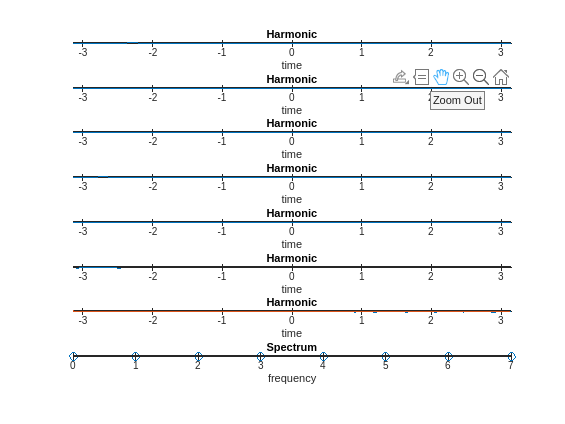

subplot(harm+1,1,harm+1)
stem([0 i],mag)
title("Spectrum")
xlabel("frequency")

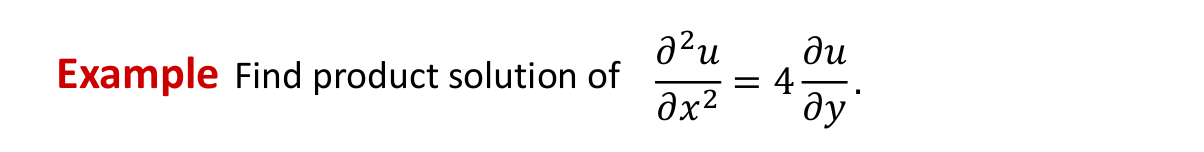

clear; clf; clc
syms x y u(x,y)

PDE

Eq=diff(u,x,2) == 4*diff(u,y)

$$Eq(x, y) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=4\,\frac{\partial }{\partial y}u\left(x,y\right)$$

syms X(x) Y(y)
SepVar = subs(Eq,u(x,y),X(x)*Y(y))

$$SepVar(x, y) = Y\left(y\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=4\,X\left(x\right)\,\frac{\partial }{\partial y}Y\left(y\right)$$

Separable variables of the equation

SepVar = SepVar/(4*X(x)*Y(y))

$$SepVar(x, y) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{4\,X\left(x\right)}=\frac{\frac{\partial }{\partial y}Y\left(y\right)}{Y\left(y\right)}$$

Serparate ODEs introduce constant(Lamda)^2

var = children(SepVar)

var = 1×2 cell array
    {[diff(X(x), x, x)/(4*X(x))]}    {[diff(Y(y), y)/Y(y)]}


syms lambda
eqX= var(1)==-lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{4\,X\left(x\right)}=-\lambda^{2}$$

eqY=var(2)==-lambda^2

$$eqY = \frac{\frac{\partial }{\partial y}Y\left(y\right)}{Y\left(y\right)}=-\lambda^{2}$$

Y(y,lambda) = dsolve(eqY)

$$Y(y, lambda) = C_{1}\,{\mathrm{e}}^{-\lambda^{2}\,y}$$

X(x,lambda) =dsolve(eqX)

$$X(x, lambda) = C_{1}\,{\mathrm{e}}^{-2\,\lambda \,x\,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{2\,\lambda \,x\,\mathrm{i}}$$